### Init and load torque from excel:

clear
% Increase default font sizes for axes, legend, and text
set(groot, 'DefaultAxesFontSize',   14);
set(groot, 'DefaultLegendFontSize', 14);
set(groot, 'DefaultTextFontSize',   14);

airfoil = Airfoil();
airfoil = airfoil.readPolar(fullfile("Airfoil H polar data","xf-n63015a-il-1000000.csv"))

airfoil =   Airfoil with properties:

            alpha: [143×1 double]
               Cl: [143×1 double]
               Cd: [143×1 double]
               Cm: [143×1 double]
       uppershape: []
       lowershape: []
    upperShapefun: []
    lowerShapefun: []
              x_c: []
           t_cfun: []
              t_c: []
             x_cm: []
               a0: 6.2093
                b: 1.8868e-06
        alphaSPos: 0.2793
        alphaSNeg: -0.2836
              CM0: 6.9641e-09
            Clmax: 1.2465


airfoil = airfoil.readShape(fullfile("Airfoil H XY data","n63015a.dat.txt"))

airfoil =   Airfoil with properties:

            alpha: [143×1 double]
               Cl: [143×1 double]
               Cd: [143×1 double]
               Cm: [143×1 double]
       uppershape: [26×2 double]
       lowershape: [26×2 double]
    upperShapefun: []
    lowerShapefun: []
              x_c: [0 0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0261 0.0281 0.0301 0.0321 0.0341 0.0361 0.0381 0.0401 0.0421 0.0441 0.0461 0.0481 0.0501 0.0521 0.0541 0.0561 0.0581 0.0601 … ] (1×500 double)
           t_cfun: []
              t_c: []
             x_cm: []
               a0: 6.2093
                b: 1.8868e-06
        alphaSPos: 0.2793
        alphaSNeg: -0.2836
              CM0: 6.9641e-09
            Clmax: 1.2465



wing_opt = WingGeometry();
wing_opt.cr = 4.24;
wing_opt.ct = 2.12;
wing_opt.ck = 2.12;
wing_opt.s = 26.41/2;
wing_opt.yk = wing_opt.s;
wing_opt.Lambdain50 = deg2rad(23);
wing_opt.Lambdaout50 = deg2rad(23);
wing_opt.N = 301;
wing_opt = wing_opt.calcSref();
wing_opt = wing_opt.createStrips();

%load("wing_opt.mat")
load("scr_s0.mat")
load("Farror.mat")
data = load("HTLoad_pos.mat")

data = struct with fields:
    HTLoad_pos: [1×1 struct]


data.HTLoad_pos.Z = flip(data.HTLoad_pos.Z);
data.HTLoad_pos.S = flip(data.HTLoad_pos.S);
data.HTLoad_pos.M = flip(data.HTLoad_pos.M);
data.HTLoad_pos.T = flip(data.HTLoad_pos.T);


y0 = [-flip(data.HTLoad_pos.Z)'; data.HTLoad_pos.Z(2:end)'];
S0 = -[flip(data.HTLoad_pos.S)'; data.HTLoad_pos.S(2:end)'];
M0 = -[flip(data.HTLoad_pos.M)'; data.HTLoad_pos.M(2:end)'];
tau0 = -[flip(data.HTLoad_pos.T)'; data.HTLoad_pos.T(2:end)'];

M = interp1(y0, M0, wing_opt.stripy,'spline');
tau = interp1(y0, tau0, wing_opt.stripy,'spline');
S = interp1(y0, S0, wing_opt.stripy,'spline');


data = load("HTLoad_neg.mat")

data = struct with fields:
    HTLoad_neg: [1×1 struct]


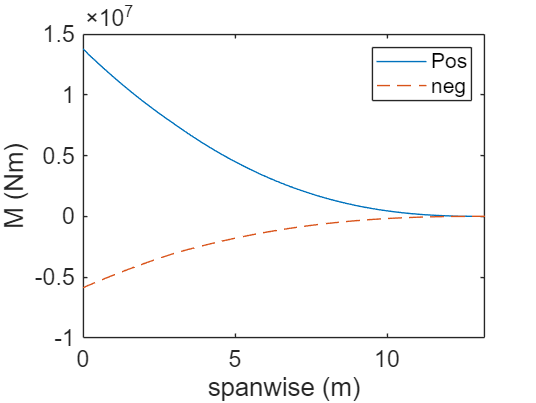

data.HTLoad_neg.Z = flip(data.HTLoad_neg.Z);
data.HTLoad_neg.S = flip(data.HTLoad_neg.S);
data.HTLoad_neg.M = flip(data.HTLoad_neg.M);
data.HTLoad_neg.T = flip(data.HTLoad_neg.T);


y0 = [-flip(data.HTLoad_neg.Z)'; data.HTLoad_neg.Z(2:end)'];
S0 = -[flip(data.HTLoad_neg.S)'; data.HTLoad_neg.S(2:end)'];
M0 = -[flip(data.HTLoad_neg.M)'; data.HTLoad_neg.M(2:end)'];
tau0 = -[flip(data.HTLoad_neg.T)'; data.HTLoad_neg.T(2:end)'];

Mneg = interp1(y0, M0, wing_opt.stripy,'spline'); 
tauneg = interp1(y0, tau0, wing_opt.stripy,'spline');
Sneg = interp1(y0, S0, wing_opt.stripy,'spline');


figure(1)
clf;
plot(wing_opt.stripy, M)
hold on
plot(y0, M0,'--')
xlabel("spanwise (m)")
ylabel("M (Nm)")
legend("Pos","neg")
xlim([0 wing_opt.b/2])

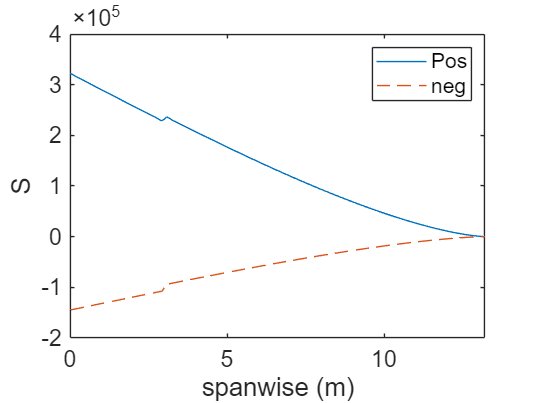


figure(2)
clf;
plot(wing_opt.stripy, S)
hold on
plot(y0, S0,'--')
xlabel("spanwise (m)")
ylabel("S")
legend("Pos","neg")
xlim([0 wing_opt.b/2])

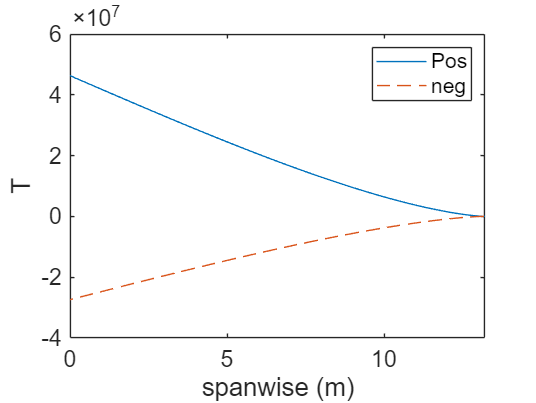



figure(3)
clf;
plot(wing_opt.stripy, tau)
hold on
plot(y0, tau0,'--')
xlabel("spanwise (m)")
ylabel("T")
legend("Pos","neg")
xlim([0 wing_opt.b/2])

Material:

Al7068 =material(); %Aluminum 2024 T861
Al7068.E = 71.2e9; %E - 72-75.7 GPa (@23degC is 73)
Al7068.sigma_y = 648e6; %sigma_y - 400-462 MPa (@23degC is 441)
Al7068.G = 28.5e9; %G - 28-29.4 GPa
Al7068.sigma_y_tensile = 683e6;
Al7068.rho = 2850;
Al7068.price = 3.61;

Al2024 = material();
Al2024.E = 72e9; %E - 72-75.7 GPa (@23degC is 73)
Al2024.sigma_y = 400e6; %sigma_y - 400-462 MPa (@23degC is 441)
Al2024.G = 28e9; %G - 28-29.4 GPa
Al2024.sigma_y_tensile = 441e6;
Al2024.rho = 2780;
Al2024.price = 1.88;

sigma_max = 296e6; %maximum allowable stress

## **WingBox geometry (unchanged throughout)**

D = 0.6*6.25;
wb = wingbox();
%define geometry
wb.b2_c = mean(airfoil.uppershape(:,2) - airfoil.lowershape(:,2));
wb.b_c = 0.12;
wb.c_c = 0.7 - wb.b_c;
%wb = wb.calcR();
wb.R_c = wb.b2_c/2;
%define stringers
wb.L = 1;
%show wingbox:
figure(1)
clf;
%wb.drawwithAirfoil(airfoil)
hold on
scatter((wb.b_c + wb.c_c)/2,0,'x')
legend("","","Aerodynamic Centre","","","","","","","","Shear Centre","Interpreter","latex")

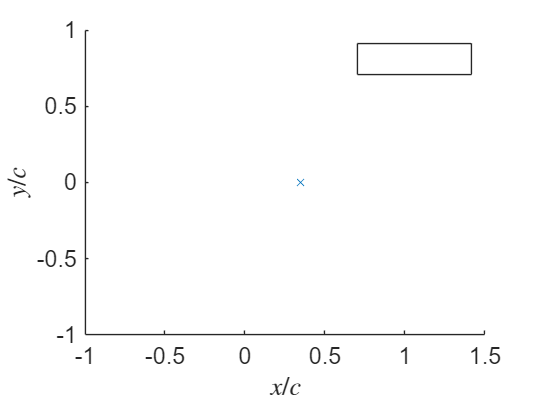

xlabel("$x/c$","Interpreter","latex")
ylabel("$y/c$","Interpreter","latex")
print(gcf, fullfile('images', 'wingbox.png'), '-dpng', '-r300');

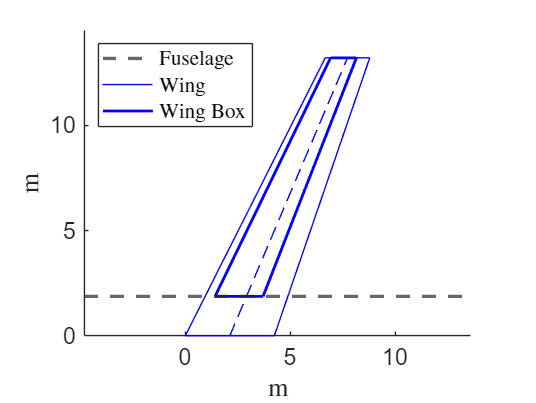


figure(2)
clf;
yline(D/2,'--','LineWidth',2)
hold on
wing_opt.plotWing()
hold on
wb.plotWingBox(wing_opt,D)
axis equal
ylim([0 wing_opt.b/2*1.1])
legend("Fuselage","","","","","","","","","","","","","","","","Wing","","","","","Wing Box","Location","northWest","Interpreter","latex")
xlabel("m","Interpreter","latex")
ylabel("m","Interpreter","latex")
print(gcf, fullfile('images', 'wingboxTopView.png'), '-dpng', '-r300');



wb = wb.calcCellArea(wing_opt);
%define rib spacing
wb.a = ones(1,length(wing_opt.stripy)).*5;
wingidx = find(wing_opt.stripy > D/2); % only consider points on the wing
ywing = wing_opt.stripy(wingidx);

Optimizing skins and spars at the same time

-upper skin: easier to buckle in compressive

-lower skin: easier to yield in tension

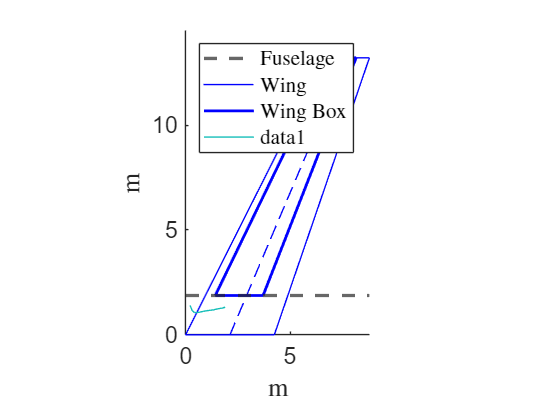

c = wb.c_c .* wing_opt.cn; 
b2 = wb.b2_c .* wing_opt.cn;
N = M ./ c ./ b2;
Nneg = Mneg ./ c ./ b2;

E = Al7068.E;
sigmaY = Al7068.sigma_y;
sigmaYT = Al7068.sigma_y_tensile;

E_L = Al7068.E;
sigmaY_L = Al7068.sigma_y;
sigmaYT_L = Al7068.sigma_y_tensile;

E_r = Al7068.E;
sigmaY_r = Al7068.sigma_y;
sigmaYT_r = Al7068.sigma_y_tensile;

rho_r = Al7068.rho;
rho_Uskin = Al7068.rho;
rho_Lskin = Al7068.rho;
d_hratio = 0.3;

sr_s0_Upper = min(sigmaY./sigma_max,1.4);
[As_bt_vals, ts_t_vals] = findAsbt_ts_for_fb_f0(sr_s0_Upper, 20, 20);

Flist = interpF(As_bt_vals, ts_t_vals);

%crush load
Fcrush = @(M,s,h,t_e,chord,E,I) (M.^2 .* s .* h .* ...
    (t_e) .* chord ./ 2) ./ ...
    (E .* I.^2);

totalM = [];
%loop for each F
wblist = [];
for i = 1:length(Flist)
    if isnan(Flist(i))
        %do nothing
    else
        F = Flist(i);
        As_bt = As_bt_vals(i);
        ts_t = ts_t_vals(i);
        thiswb = wb;
        
        %input upper skin thickness
        t = max(0e-3,N./sigmaY);
        ts = t.*ts_t;
        thiswb.t_Upper = thicknessDoubler(t,wing_opt.stripy,D);
        thiswb.ts_Upper = thicknessDoubler(ts,wing_opt.stripy,D);
        
        %1. upper skin mass
        [thiswb.bs_Upper,thiswb.hs,thiswb.Ks_Upper,thiswb.F,thiswb.sr_s0] = findbs(thiswb.t_Upper, sigmaY, sr_s0_Upper, 3.61, E,As_bt,ts_t,1e-2);
        thiswb.ds = thiswb.hs.*0.3;
        [Mass_Uskin,~,~,thiswb.b1_c] = UskinMass(rho_Uskin, wing_opt, thiswb, wingidx)
        %get rib spacing, becareful with saturation
        thiswb.L = max(N.*E.*(sigmaY./thiswb.F).^(-2), 0.2);
        
        %2. lower skin mass
        %input lower skin thickness
        t_Lower = max(0e-3,N./sigma_max);
        ts_Lower =t_Lower.*ts_t;
        thiswb.t_Lower = thicknessDoubler(t_Lower,wing_opt.stripy,D);
        thiswb.ts_Lower = thicknessDoubler(ts_Lower,wing_opt.stripy,D);
        [thiswb.bs_Lower,thiswb.hs_Lower,thiswb.Ks_Lower,thiswb.F_Lower,thiswb.sr_s0_Lower] = findbs(thiswb.t_Lower, sigmaY_L, sr_s0_Upper, 3.61, E,As_bt,ts_t,1e-2);
        thiswb.ds_Lower = thiswb.hs_Lower.*0.3;
        [Mass_Lskin,~,~,thiswb.b1_c_Lower] = LskinMass(rho_Lskin, wing_opt, thiswb, wingidx)

        %3. rib
        thiswb = thiswb.calcStringerArea();
        thiswb = thiswb.calcStringerArea_Lower();
        h = thiswb.b2_c.*wing_opt.cn;

        t_eff_upper = thiswb.t_Upper + thiswb.As./thiswb.bs_Upper;
        t_eff_upper(isnan(t_eff_upper)) = 0;
        t_eff_lower = thiswb.t_Lower + thiswb.As_Lower./thiswb.bs_Lower;
        t_eff_lower(isnan(t_eff_lower)) = 0;
        chord = wing_opt.cn;
        I_Upper = chord .* (t_eff_upper).^3 ./ 12 + chord .* (t_eff_upper) .* (h./2).^2;
        I_Lower = chord .* (t_eff_lower).^3 ./ 12 + chord .* (t_eff_lower) .* (h./2).^2;

        
        [thiswb.yrib, thiswb.Nrib] = createRibLocationsFromL(thiswb.L, wing_opt, D);
        thiswb = thiswb.mapRibSpacing(wing_opt,D);
        thiswb.L = thiswb.L(152:end);
        thiswb.L = [flip(thiswb.L),NaN,thiswb.L];
        
        %find crush load of all case
        F_pos_upper = abs(Fcrush(M, thiswb.L, h, t_eff_upper, wing_opt.cn, E_r, I_Lower + I_Upper));
        F_neg_upper = abs(Fcrush(Mneg, thiswb.L, h, t_eff_upper, wing_opt.cn, E_r, I_Lower + I_Upper));
        F_pos_lower = abs(Fcrush(M, thiswb.L,h, t_eff_lower, wing_opt.cn, E_r, I_Lower + I_Upper));
        F_neg_lower = abs(Fcrush(Mneg, thiswb.L, h, t_eff_lower, wing_opt.cn, E_r, I_Lower + I_Upper));
        %find the maximum among these
        arrays = {F_pos_upper(wingidx), F_neg_upper(wingidx), F_pos_lower(wingidx), F_neg_lower(wingidx)};
        max_values = cellfun(@(x) max(x(:)), arrays);
        [~, idx] = max(max_values);
        Flarge = arrays{idx};
        
        tr1 = Flarge ./ sigmaY_r ./ wing_opt.cn(wingidx);
        tr2 = (Flarge.*h(wingidx).^2./(3.62.*E_r.*wing_opt.cn(wingidx))).^(1/3);
        tr_max = max(tr1, tr2);
        thiswb.tr = interp1(wing_opt.stripy(wingidx),tr_max,thiswb.yrib(length(thiswb.yrib)/2+1:end));
        thiswb.tr = max(thiswb.tr, 3e-3);
        thiswb.tr = [flip(thiswb.tr); thiswb.tr]
        Mrib = ribMass(thiswb, wing_opt, rho_r)
        
        totalM(i) = Mrib + Mass_Lskin + Mass_Uskin
        wblist = [wblist thiswb];
    end
end

Mass_Uskin = 1.9721e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0544 0.0541 0.0537 0.0534 0.0530 0.0527 0.0523 0.0520 0.0517 0.0513 0.0510 0.0507 0.0504 0.0501 0.0498 0.0495 0.0492 0.0489 0.0486 0.0483 0.0480 0.0477 0.0475 0.0472 0.0469 0.0466 0.0464 0.0461 0.0459 0.0456 0.0454 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.1154 0.1154 0.1154 0.1154 0.1154 0.1154 0.1154 0.1154 0.1154 0.1154 0.1154 0.1154 0.1154 0.1154 0.1154 0.1154 0.1154 0.1154 0.1154 0.1154 0.1154 0.1154 0.1154 0.1154 0.1154 0.1154 0.1154 0.1154 0.1154 0.1154 0.1154 … ] (1×301 double)
       bs_

Mass_Lskin = 4.2398e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0544 0.0541 0.0537 0.0534 0.0530 0.0527 0.0523 0.0520 0.0517 0.0513 0.0510 0.0507 0.0504 0.0501 0.0498 0.0495 0.0492 0.0489 0.0486 0.0483 0.0480 0.0477 0.0475 0.0472 0.0469 0.0466 0.0464 0.0461 0.0459 0.0456 0.0454 … ] (1×301 double)
     b1_c_Lower: [0.1225 0.1216 0.1208 0.1200 0.11

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0544 0.0541 0.0537 0.0534 0.0530 0.0527 0.0523 0.0520 0.0517 0.0513 0.0510 0.0507 0.0504 0.0501 0.0498 0.0495 0.0492 0.0489 0.0486 0.0483 0.0480 0.0477 0.0475 0.0472 0.0469 0.0466 0.0464 0.0461 0.0459 0.0456 0.0454 … ] (1×301 double)
     b1_c_Lower: [0.1225 0.1216 0.1208 0.1200 0.11

Mrib = 319.1523

totalM = 1.0e+03 *

         0         0         0         0         0         0    6.5311


Mass_Uskin = 2.0483e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0535 0.0531 0.0528 0.0525 0.0521 0.0518 0.0514 0.0511 0.0508 0.0505 0.0502 0.0498 0.0495 0.0492 0.0489 0.0486 0.0483 0.0481 0.0478 0.0475 0.0472 0.0469 0.0467 0.0464 0.0461 0.0459 0.0456 0.0453 0.0451 0.0448 0.0446 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.1134 0.1134 0.1134 0.1134 0.1134 0.1134 0.1134 0.1134 0.1134 0.1134 0.1134 0.1134 0.1134 0.1134 0.1134 0.1134 0.1134 0.1134 0.1134 0.1134 0.1134 0.1134 0.1134 0.1134 0.1134 0.1134 0.1134 0.1134 0.1134 0.1134 0.1134 … ] (1×301 double)
       bs_

Mass_Lskin = 4.3833e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0535 0.0531 0.0528 0.0525 0.0521 0.0518 0.0514 0.0511 0.0508 0.0505 0.0502 0.0498 0.0495 0.0492 0.0489 0.0486 0.0483 0.0481 0.0478 0.0475 0.0472 0.0469 0.0467 0.0464 0.0461 0.0459 0.0456 0.0453 0.0451 0.0448 0.0446 … ] (1×301 double)
     b1_c_Lower: [0.1204 0.1196 0.1188 0.1180 0.11

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0535 0.0531 0.0528 0.0525 0.0521 0.0518 0.0514 0.0511 0.0508 0.0505 0.0502 0.0498 0.0495 0.0492 0.0489 0.0486 0.0483 0.0481 0.0478 0.0475 0.0472 0.0469 0.0467 0.0464 0.0461 0.0459 0.0456 0.0453 0.0451 0.0448 0.0446 … ] (1×301 double)
     b1_c_Lower: [0.1204 0.1196 0.1188 0.1180 0.11

Mrib = 291.6371

totalM = 1.0e+03 *

         0         0         0         0         0         0    6.5311    6.7232


Mass_Uskin = 2.0843e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0529 0.0525 0.0522 0.0518 0.0515 0.0512 0.0508 0.0505 0.0502 0.0499 0.0496 0.0492 0.0489 0.0486 0.0483 0.0481 0.0478 0.0475 0.0472 0.0469 0.0466 0.0464 0.0461 0.0458 0.0456 0.0453 0.0450 0.0448 0.0445 0.0443 0.0440 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.1121 0.1121 0.1121 0.1121 0.1121 0.1121 0.1121 0.1121 0.1121 0.1121 0.1121 0.1121 0.1121 0.1121 0.1121 0.1121 0.1121 0.1121 0.1121 0.1121 0.1121 0.1121 0.1121 0.1121 0.1121 0.1121 0.1121 0.1121 0.1121 0.1121 0.1121 … ] (1×301 double)
       bs_

Mass_Lskin = 4.4587e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0529 0.0525 0.0522 0.0518 0.0515 0.0512 0.0508 0.0505 0.0502 0.0499 0.0496 0.0492 0.0489 0.0486 0.0483 0.0481 0.0478 0.0475 0.0472 0.0469 0.0466 0.0464 0.0461 0.0458 0.0456 0.0453 0.0450 0.0448 0.0445 0.0443 0.0440 … ] (1×301 double)
     b1_c_Lower: [0.1189 0.1181 0.1174 0.1166 0.11

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0529 0.0525 0.0522 0.0518 0.0515 0.0512 0.0508 0.0505 0.0502 0.0499 0.0496 0.0492 0.0489 0.0486 0.0483 0.0481 0.0478 0.0475 0.0472 0.0469 0.0466 0.0464 0.0461 0.0458 0.0456 0.0453 0.0450 0.0448 0.0445 0.0443 0.0440 … ] (1×301 double)
     b1_c_Lower: [0.1189 0.1181 0.1174 0.1166 0.11

Mrib = 282.3203

totalM = 1.0e+03 *

         0         0         0         0         0         0    6.5311    6.7232    6.8253


Mass_Uskin = 2.2363e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0523 0.0520 0.0516 0.0513 0.0510 0.0506 0.0503 0.0500 0.0497 0.0494 0.0491 0.0487 0.0484 0.0482 0.0479 0.0476 0.0473 0.0470 0.0467 0.0464 0.0462 0.0459 0.0456 0.0454 0.0451 0.0448 0.0446 0.0443 0.0441 0.0438 0.0436 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 … ] (1×301 double)
       bs_

Mass_Lskin = 4.7799e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0523 0.0520 0.0516 0.0513 0.0510 0.0506 0.0503 0.0500 0.0497 0.0494 0.0491 0.0487 0.0484 0.0482 0.0479 0.0476 0.0473 0.0470 0.0467 0.0464 0.0462 0.0459 0.0456 0.0454 0.0451 0.0448 0.0446 0.0443 0.0441 0.0438 0.0436 … ] (1×301 double)
     b1_c_Lower: [0.1177 0.1169 0.1162 0.1154 0.11

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0523 0.0520 0.0516 0.0513 0.0510 0.0506 0.0503 0.0500 0.0497 0.0494 0.0491 0.0487 0.0484 0.0482 0.0479 0.0476 0.0473 0.0470 0.0467 0.0464 0.0462 0.0459 0.0456 0.0454 0.0451 0.0448 0.0446 0.0443 0.0441 0.0438 0.0436 … ] (1×301 double)
     b1_c_Lower: [0.1177 0.1169 0.1162 0.1154 0.11

Mrib = 248.5568

totalM = 1.0e+03 *

         0         0         0         0         0         0    6.5311    6.7232    6.8253    7.2647


Mass_Uskin = 2.4012e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0520 0.0517 0.0513 0.0510 0.0507 0.0503 0.0500 0.0497 0.0494 0.0491 0.0488 0.0485 0.0482 0.0479 0.0476 0.0473 0.0470 0.0467 0.0464 0.0462 0.0459 0.0456 0.0454 0.0451 0.0448 0.0446 0.0443 0.0441 0.0438 0.0436 0.0433 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.1103 0.1103 0.1103 0.1103 0.1103 0.1103 0.1103 0.1103 0.1103 0.1103 0.1103 0.1103 0.1103 0.1103 0.1103 0.1103 0.1103 0.1103 0.1103 0.1103 0.1103 0.1103 0.1103 0.1103 0.1103 0.1103 0.1103 0.1103 0.1103 0.1103 0.1103 … ] (1×301 double)
       bs_

Mass_Lskin = 5.1295e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0520 0.0517 0.0513 0.0510 0.0507 0.0503 0.0500 0.0497 0.0494 0.0491 0.0488 0.0485 0.0482 0.0479 0.0476 0.0473 0.0470 0.0467 0.0464 0.0462 0.0459 0.0456 0.0454 0.0451 0.0448 0.0446 0.0443 0.0441 0.0438 0.0436 0.0433 … ] (1×301 double)
     b1_c_Lower: [0.1170 0.1162 0.1155 0.1147 0.11

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0520 0.0517 0.0513 0.0510 0.0507 0.0503 0.0500 0.0497 0.0494 0.0491 0.0488 0.0485 0.0482 0.0479 0.0476 0.0473 0.0470 0.0467 0.0464 0.0462 0.0459 0.0456 0.0454 0.0451 0.0448 0.0446 0.0443 0.0441 0.0438 0.0436 0.0433 … ] (1×301 double)
     b1_c_Lower: [0.1170 0.1162 0.1155 0.1147 0.11

Mrib = 238.6760

totalM = 1.0e+03 *

         0         0         0         0         0         0    6.5311    6.7232    6.8253    7.2647    7.7694


Mass_Uskin = 2.4725e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0519 0.0516 0.0512 0.0509 0.0506 0.0503 0.0499 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0469 0.0466 0.0464 0.0461 0.0458 0.0455 0.0453 0.0450 0.0448 0.0445 0.0443 0.0440 0.0438 0.0435 0.0433 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 … ] (1×301 double)
       bs_

Mass_Lskin = 5.2801e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0519 0.0516 0.0512 0.0509 0.0506 0.0503 0.0499 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0469 0.0466 0.0464 0.0461 0.0458 0.0455 0.0453 0.0450 0.0448 0.0445 0.0443 0.0440 0.0438 0.0435 0.0433 … ] (1×301 double)
     b1_c_Lower: [0.1168 0.1161 0.1153 0.1145 0.11

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0519 0.0516 0.0512 0.0509 0.0506 0.0503 0.0499 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0469 0.0466 0.0464 0.0461 0.0458 0.0455 0.0453 0.0450 0.0448 0.0445 0.0443 0.0440 0.0438 0.0435 0.0433 … ] (1×301 double)
     b1_c_Lower: [0.1168 0.1161 0.1153 0.1145 0.11

Mrib = 230.4185

totalM = 1.0e+03 *

         0         0         0         0         0         0    6.5311    6.7232    6.8253    7.2647    7.7694    7.9830


Mass_Uskin = 2.5568e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0519 0.0516 0.0512 0.0509 0.0506 0.0502 0.0499 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0469 0.0466 0.0463 0.0461 0.0458 0.0455 0.0453 0.0450 0.0447 0.0445 0.0442 0.0440 0.0437 0.0435 0.0433 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 … ] (1×301 double)
       bs_

Mass_Lskin = 5.4351e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0519 0.0516 0.0512 0.0509 0.0506 0.0502 0.0499 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0469 0.0466 0.0463 0.0461 0.0458 0.0455 0.0453 0.0450 0.0447 0.0445 0.0442 0.0440 0.0437 0.0435 0.0433 … ] (1×301 double)
     b1_c_Lower: [0.1168 0.1160 0.1153 0.1145 0.11

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0519 0.0516 0.0512 0.0509 0.0506 0.0502 0.0499 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0469 0.0466 0.0463 0.0461 0.0458 0.0455 0.0453 0.0450 0.0447 0.0445 0.0442 0.0440 0.0437 0.0435 0.0433 … ] (1×301 double)
     b1_c_Lower: [0.1168 0.1160 0.1153 0.1145 0.11

Mrib = 222.8666

totalM = 1.0e+03 *

         0         0         0         0         0         0    6.5311    6.7232    6.8253    7.2647    7.7694    7.9830    8.2147


Mass_Uskin = 2.6839e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0519 0.0516 0.0512 0.0509 0.0506 0.0502 0.0499 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0469 0.0466 0.0464 0.0461 0.0458 0.0455 0.0453 0.0450 0.0448 0.0445 0.0443 0.0440 0.0438 0.0435 0.0433 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 … ] (1×301 double)
       bs_

Mass_Lskin = 5.7860e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0519 0.0516 0.0512 0.0509 0.0506 0.0502 0.0499 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0469 0.0466 0.0464 0.0461 0.0458 0.0455 0.0453 0.0450 0.0448 0.0445 0.0443 0.0440 0.0438 0.0435 0.0433 … ] (1×301 double)
     b1_c_Lower: [0.1168 0.1161 0.1153 0.1145 0.11

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0519 0.0516 0.0512 0.0509 0.0506 0.0502 0.0499 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0469 0.0466 0.0464 0.0461 0.0458 0.0455 0.0453 0.0450 0.0448 0.0445 0.0443 0.0440 0.0438 0.0435 0.0433 … ] (1×301 double)
     b1_c_Lower: [0.1168 0.1161 0.1153 0.1145 0.11

Mrib = 214.1840

totalM = 1.0e+03 *

         0         0         0         0         0         0    6.5311    6.7232    6.8253    7.2647    7.7694    7.9830    8.2147    8.6841


Mass_Uskin = 2.8258e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0519 0.0515 0.0512 0.0508 0.0505 0.0502 0.0499 0.0496 0.0492 0.0489 0.0486 0.0483 0.0480 0.0477 0.0474 0.0472 0.0469 0.0466 0.0463 0.0460 0.0458 0.0455 0.0452 0.0450 0.0447 0.0445 0.0442 0.0440 0.0437 0.0435 0.0432 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 … ] (1×301 double)
       bs_

Mass_Lskin = 6.0742e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0519 0.0515 0.0512 0.0508 0.0505 0.0502 0.0499 0.0496 0.0492 0.0489 0.0486 0.0483 0.0480 0.0477 0.0474 0.0472 0.0469 0.0466 0.0463 0.0460 0.0458 0.0455 0.0452 0.0450 0.0447 0.0445 0.0442 0.0440 0.0437 0.0435 0.0432 … ] (1×301 double)
     b1_c_Lower: [0.1167 0.1159 0.1152 0.1144 0.11

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0519 0.0515 0.0512 0.0508 0.0505 0.0502 0.0499 0.0496 0.0492 0.0489 0.0486 0.0483 0.0480 0.0477 0.0474 0.0472 0.0469 0.0466 0.0463 0.0460 0.0458 0.0455 0.0452 0.0450 0.0447 0.0445 0.0442 0.0440 0.0437 0.0435 0.0432 … ] (1×301 double)
     b1_c_Lower: [0.1167 0.1159 0.1152 0.1144 0.11

Mrib = 206.8570

totalM = 1.0e+03 *

         0         0         0         0         0         0    6.5311    6.7232    6.8253    7.2647    7.7694    7.9830    8.2147    8.6841    9.1068


Mass_Uskin = 2.8479e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0519 0.0515 0.0512 0.0509 0.0505 0.0502 0.0499 0.0496 0.0492 0.0489 0.0486 0.0483 0.0480 0.0477 0.0474 0.0472 0.0469 0.0466 0.0463 0.0460 0.0458 0.0455 0.0452 0.0450 0.0447 0.0445 0.0442 0.0440 0.0437 0.0435 0.0432 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 0.1100 … ] (1×301 double)
       bs_

Mass_Lskin = 6.1217e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0519 0.0515 0.0512 0.0509 0.0505 0.0502 0.0499 0.0496 0.0492 0.0489 0.0486 0.0483 0.0480 0.0477 0.0474 0.0472 0.0469 0.0466 0.0463 0.0460 0.0458 0.0455 0.0452 0.0450 0.0447 0.0445 0.0442 0.0440 0.0437 0.0435 0.0432 … ] (1×301 double)
     b1_c_Lower: [0.1167 0.1159 0.1152 0.1144 0.11

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0519 0.0515 0.0512 0.0509 0.0505 0.0502 0.0499 0.0496 0.0492 0.0489 0.0486 0.0483 0.0480 0.0477 0.0474 0.0472 0.0469 0.0466 0.0463 0.0460 0.0458 0.0455 0.0452 0.0450 0.0447 0.0445 0.0442 0.0440 0.0437 0.0435 0.0432 … ] (1×301 double)
     b1_c_Lower: [0.1167 0.1159 0.1152 0.1144 0.11

Mrib = 206.5238

totalM = 1.0e+03 *

         0         0         0         0         0         0    6.5311    6.7232    6.8253    7.2647    7.7694    7.9830    8.2147    8.6841    9.1068    9.1760


Mass_Uskin = 3.0150e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0518 0.0515 0.0512 0.0508 0.0505 0.0502 0.0498 0.0495 0.0492 0.0489 0.0486 0.0483 0.0480 0.0477 0.0474 0.0471 0.0468 0.0466 0.0463 0.0460 0.0457 0.0455 0.0452 0.0449 0.0447 0.0444 0.0442 0.0439 0.0437 0.0434 0.0432 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.1099 0.1099 0.1099 0.1099 0.1099 0.1099 0.1099 0.1099 0.1099 0.1099 0.1099 0.1099 0.1099 0.1099 0.1099 0.1099 0.1099 0.1099 0.1099 0.1099 0.1099 0.1099 0.1099 0.1099 0.1099 0.1099 0.1099 0.1099 0.1099 0.1099 0.1099 … ] (1×301 double)
       bs_

Mass_Lskin = 6.4483e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0518 0.0515 0.0512 0.0508 0.0505 0.0502 0.0498 0.0495 0.0492 0.0489 0.0486 0.0483 0.0480 0.0477 0.0474 0.0471 0.0468 0.0466 0.0463 0.0460 0.0457 0.0455 0.0452 0.0449 0.0447 0.0444 0.0442 0.0439 0.0437 0.0434 0.0432 … ] (1×301 double)
     b1_c_Lower: [0.1166 0.1159 0.1151 0.1143 0.11

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0518 0.0515 0.0512 0.0508 0.0505 0.0502 0.0498 0.0495 0.0492 0.0489 0.0486 0.0483 0.0480 0.0477 0.0474 0.0471 0.0468 0.0466 0.0463 0.0460 0.0457 0.0455 0.0452 0.0449 0.0447 0.0444 0.0442 0.0439 0.0437 0.0434 0.0432 … ] (1×301 double)
     b1_c_Lower: [0.1166 0.1159 0.1151 0.1143 0.11

Mrib = 204.5487

totalM = 1.0e+03 *

         0         0         0         0         0         0    6.5311    6.7232    6.8253    7.2647    7.7694    7.9830    8.2147    8.6841    9.1068    9.1760    9.6678


Mass_Uskin = 3.1428e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0519 0.0516 0.0513 0.0509 0.0506 0.0503 0.0499 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0469 0.0467 0.0464 0.0461 0.0458 0.0456 0.0453 0.0450 0.0448 0.0445 0.0443 0.0440 0.0438 0.0435 0.0433 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 … ] (1×301 double)
       bs_

Mass_Lskin = 6.7202e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0519 0.0516 0.0513 0.0509 0.0506 0.0503 0.0499 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0469 0.0467 0.0464 0.0461 0.0458 0.0456 0.0453 0.0450 0.0448 0.0445 0.0443 0.0440 0.0438 0.0435 0.0433 … ] (1×301 double)
     b1_c_Lower: [0.1169 0.1161 0.1153 0.1146 0.11

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0519 0.0516 0.0513 0.0509 0.0506 0.0503 0.0499 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0469 0.0467 0.0464 0.0461 0.0458 0.0456 0.0453 0.0450 0.0448 0.0445 0.0443 0.0440 0.0438 0.0435 0.0433 … ] (1×301 double)
     b1_c_Lower: [0.1169 0.1161 0.1153 0.1146 0.11

Mrib = 197.4335

totalM = 1.0e+04 *

         0         0         0         0         0         0    0.6531    0.6723    0.6825    0.7265    0.7769    0.7983    0.8215    0.8684    0.9107    0.9176    0.9668    1.0060


Mass_Uskin = 3.2744e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0519 0.0516 0.0512 0.0509 0.0506 0.0502 0.0499 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0469 0.0466 0.0464 0.0461 0.0458 0.0455 0.0453 0.0450 0.0448 0.0445 0.0443 0.0440 0.0438 0.0435 0.0433 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 … ] (1×301 double)
       bs_

Mass_Lskin = 7.0827e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0519 0.0516 0.0512 0.0509 0.0506 0.0502 0.0499 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0469 0.0466 0.0464 0.0461 0.0458 0.0455 0.0453 0.0450 0.0448 0.0445 0.0443 0.0440 0.0438 0.0435 0.0433 … ] (1×301 double)
     b1_c_Lower: [0.1168 0.1161 0.1153 0.1145 0.11

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0519 0.0516 0.0512 0.0509 0.0506 0.0502 0.0499 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0469 0.0466 0.0464 0.0461 0.0458 0.0455 0.0453 0.0450 0.0448 0.0445 0.0443 0.0440 0.0438 0.0435 0.0433 … ] (1×301 double)
     b1_c_Lower: [0.1168 0.1161 0.1153 0.1145 0.11

Mrib = 196.2730

totalM = 1.0e+04 *

         0         0         0         0         0         0    0.6531    0.6723    0.6825    0.7265    0.7769    0.7983    0.8215    0.8684    0.9107    0.9176    0.9668    1.0060    1.0553


Mass_Uskin = 3.3847e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0519 0.0516 0.0512 0.0509 0.0506 0.0503 0.0499 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0469 0.0466 0.0464 0.0461 0.0458 0.0455 0.0453 0.0450 0.0448 0.0445 0.0443 0.0440 0.0438 0.0435 0.0433 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 0.1101 … ] (1×301 double)
       bs_

Mass_Lskin = 7.2475e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0519 0.0516 0.0512 0.0509 0.0506 0.0503 0.0499 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0469 0.0466 0.0464 0.0461 0.0458 0.0455 0.0453 0.0450 0.0448 0.0445 0.0443 0.0440 0.0438 0.0435 0.0433 … ] (1×301 double)
     b1_c_Lower: [0.1168 0.1161 0.1153 0.1145 0.11

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0519 0.0516 0.0512 0.0509 0.0506 0.0503 0.0499 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0469 0.0466 0.0464 0.0461 0.0458 0.0455 0.0453 0.0450 0.0448 0.0445 0.0443 0.0440 0.0438 0.0435 0.0433 … ] (1×301 double)
     b1_c_Lower: [0.1168 0.1161 0.1153 0.1145 0.11

Mrib = 195.6728

totalM = 1.0e+04 *

         0         0         0         0         0         0    0.6531    0.6723    0.6825    0.7265    0.7769    0.7983    0.8215    0.8684    0.9107    0.9176    0.9668    1.0060    1.0553    1.0828


Mass_Uskin = 3.4327e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0521 0.0517 0.0514 0.0510 0.0507 0.0504 0.0501 0.0497 0.0494 0.0491 0.0488 0.0485 0.0482 0.0479 0.0476 0.0473 0.0470 0.0468 0.0465 0.0462 0.0459 0.0457 0.0454 0.0451 0.0449 0.0446 0.0444 0.0441 0.0439 0.0436 0.0434 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.1104 0.1104 0.1104 0.1104 0.1104 0.1104 0.1104 0.1104 0.1104 0.1104 0.1104 0.1104 0.1104 0.1104 0.1104 0.1104 0.1104 0.1104 0.1104 0.1104 0.1104 0.1104 0.1104 0.1104 0.1104 0.1104 0.1104 0.1104 0.1104 0.1104 0.1104 … ] (1×301 double)
       bs_

Mass_Lskin = 7.3853e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0521 0.0517 0.0514 0.0510 0.0507 0.0504 0.0501 0.0497 0.0494 0.0491 0.0488 0.0485 0.0482 0.0479 0.0476 0.0473 0.0470 0.0468 0.0465 0.0462 0.0459 0.0457 0.0454 0.0451 0.0449 0.0446 0.0444 0.0441 0.0439 0.0436 0.0434 … ] (1×301 double)
     b1_c_Lower: [0.1171 0.1163 0.1156 0.1148 0.11

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0521 0.0517 0.0514 0.0510 0.0507 0.0504 0.0501 0.0497 0.0494 0.0491 0.0488 0.0485 0.0482 0.0479 0.0476 0.0473 0.0470 0.0468 0.0465 0.0462 0.0459 0.0457 0.0454 0.0451 0.0449 0.0446 0.0444 0.0441 0.0439 0.0436 0.0434 … ] (1×301 double)
     b1_c_Lower: [0.1171 0.1163 0.1156 0.1148 0.11

Mrib = 189.3609

totalM = 1.0e+04 *

         0         0         0         0         0         0    0.6531    0.6723    0.6825    0.7265    0.7769    0.7983    0.8215    0.8684    0.9107    0.9176    0.9668    1.0060    1.0553    1.0828    1.1007


Mass_Uskin = 3.5941e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0523 0.0519 0.0516 0.0513 0.0509 0.0506 0.0503 0.0500 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0470 0.0467 0.0464 0.0461 0.0459 0.0456 0.0453 0.0451 0.0448 0.0446 0.0443 0.0441 0.0438 0.0436 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 … ] (1×301 double)
       bs_

Mass_Lskin = 7.7486e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0523 0.0519 0.0516 0.0513 0.0509 0.0506 0.0503 0.0500 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0470 0.0467 0.0464 0.0461 0.0459 0.0456 0.0453 0.0451 0.0448 0.0446 0.0443 0.0441 0.0438 0.0436 … ] (1×301 double)
     b1_c_Lower: [0.1176 0.1169 0.1161 0.1153 0.11

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0523 0.0519 0.0516 0.0513 0.0509 0.0506 0.0503 0.0500 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0470 0.0467 0.0464 0.0461 0.0459 0.0456 0.0453 0.0451 0.0448 0.0446 0.0443 0.0441 0.0438 0.0436 … ] (1×301 double)
     b1_c_Lower: [0.1176 0.1169 0.1161 0.1153 0.11

Mrib = 188.8459

totalM = 1.0e+04 *

         0         0         0         0         0         0    0.6531    0.6723    0.6825    0.7265    0.7769    0.7983    0.8215    0.8684    0.9107    0.9176    0.9668    1.0060    1.0553    1.0828    1.1007    1.1532


Mass_Uskin = 3.7454e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0523 0.0520 0.0516 0.0513 0.0509 0.0506 0.0503 0.0500 0.0497 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0476 0.0473 0.0470 0.0467 0.0464 0.0462 0.0459 0.0456 0.0454 0.0451 0.0448 0.0446 0.0443 0.0441 0.0438 0.0436 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 … ] (1×301 double)
       bs_

Mass_Lskin = 8.0886e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0523 0.0520 0.0516 0.0513 0.0509 0.0506 0.0503 0.0500 0.0497 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0476 0.0473 0.0470 0.0467 0.0464 0.0462 0.0459 0.0456 0.0454 0.0451 0.0448 0.0446 0.0443 0.0441 0.0438 0.0436 … ] (1×301 double)
     b1_c_Lower: [0.1177 0.1169 0.1161 0.1154 0.11

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0523 0.0520 0.0516 0.0513 0.0509 0.0506 0.0503 0.0500 0.0497 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0476 0.0473 0.0470 0.0467 0.0464 0.0462 0.0459 0.0456 0.0454 0.0451 0.0448 0.0446 0.0443 0.0441 0.0438 0.0436 … ] (1×301 double)
     b1_c_Lower: [0.1177 0.1169 0.1161 0.1154 0.11

Mrib = 188.1810

totalM = 1.0e+04 *

         0         0         0         0         0         0    0.6531    0.6723    0.6825    0.7265    0.7769    0.7983    0.8215    0.8684    0.9107    0.9176    0.9668    1.0060    1.0553    1.0828    1.1007    1.1532    1.2022


Mass_Uskin = 3.7503e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0523 0.0520 0.0516 0.0513 0.0510 0.0506 0.0503 0.0500 0.0497 0.0494 0.0490 0.0487 0.0484 0.0481 0.0478 0.0476 0.0473 0.0470 0.0467 0.0464 0.0462 0.0459 0.0456 0.0454 0.0451 0.0448 0.0446 0.0443 0.0441 0.0438 0.0436 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 0.1109 … ] (1×301 double)
       bs_

Mass_Lskin = 8.0992e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0523 0.0520 0.0516 0.0513 0.0510 0.0506 0.0503 0.0500 0.0497 0.0494 0.0490 0.0487 0.0484 0.0481 0.0478 0.0476 0.0473 0.0470 0.0467 0.0464 0.0462 0.0459 0.0456 0.0454 0.0451 0.0448 0.0446 0.0443 0.0441 0.0438 0.0436 … ] (1×301 double)
     b1_c_Lower: [0.1177 0.1169 0.1162 0.1154 0.11

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0523 0.0520 0.0516 0.0513 0.0510 0.0506 0.0503 0.0500 0.0497 0.0494 0.0490 0.0487 0.0484 0.0481 0.0478 0.0476 0.0473 0.0470 0.0467 0.0464 0.0462 0.0459 0.0456 0.0454 0.0451 0.0448 0.0446 0.0443 0.0441 0.0438 0.0436 … ] (1×301 double)
     b1_c_Lower: [0.1177 0.1169 0.1162 0.1154 0.11

Mrib = 188.1751

totalM = 1.0e+04 *

         0         0         0         0         0         0    0.6531    0.6723    0.6825    0.7265    0.7769    0.7983    0.8215    0.8684    0.9107    0.9176    0.9668    1.0060    1.0553    1.0828    1.1007    1.1532    1.2022    1.2038


Mass_Uskin = 3.8625e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0523 0.0519 0.0516 0.0512 0.0509 0.0506 0.0503 0.0499 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0469 0.0467 0.0464 0.0461 0.0459 0.0456 0.0453 0.0451 0.0448 0.0445 0.0443 0.0440 0.0438 0.0436 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 … ] (1×301 double)
       bs_

Mass_Lskin = 8.3833e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0523 0.0519 0.0516 0.0512 0.0509 0.0506 0.0503 0.0499 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0469 0.0467 0.0464 0.0461 0.0459 0.0456 0.0453 0.0451 0.0448 0.0445 0.0443 0.0440 0.0438 0.0436 … ] (1×301 double)
     b1_c_Lower: [0.1176 0.1168 0.1161 0.1153 0.11

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0523 0.0519 0.0516 0.0512 0.0509 0.0506 0.0503 0.0499 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0469 0.0467 0.0464 0.0461 0.0459 0.0456 0.0453 0.0451 0.0448 0.0445 0.0443 0.0440 0.0438 0.0436 … ] (1×301 double)
     b1_c_Lower: [0.1176 0.1168 0.1161 0.1153 0.11

Mrib = 187.7392

totalM = 1.0e+04 *

         0         0         0         0         0         0    0.6531    0.6723    0.6825    0.7265    0.7769    0.7983    0.8215    0.8684    0.9107    0.9176    0.9668    1.0060    1.0553    1.0828    1.1007    1.1532    1.2022    1.2038    1.2433


Mass_Uskin = 4.0408e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0521 0.0518 0.0515 0.0511 0.0508 0.0505 0.0501 0.0498 0.0495 0.0492 0.0489 0.0486 0.0483 0.0480 0.0477 0.0474 0.0471 0.0468 0.0466 0.0463 0.0460 0.0457 0.0455 0.0452 0.0450 0.0447 0.0444 0.0442 0.0439 0.0437 0.0435 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.1106 0.1106 0.1106 0.1106 0.1106 0.1106 0.1106 0.1106 0.1106 0.1106 0.1106 0.1106 0.1106 0.1106 0.1106 0.1106 0.1106 0.1106 0.1106 0.1106 0.1106 0.1106 0.1106 0.1106 0.1106 0.1106 0.1106 0.1106 0.1106 0.1106 0.1106 … ] (1×301 double)
       bs_

Mass_Lskin = 8.7396e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0521 0.0518 0.0515 0.0511 0.0508 0.0505 0.0501 0.0498 0.0495 0.0492 0.0489 0.0486 0.0483 0.0480 0.0477 0.0474 0.0471 0.0468 0.0466 0.0463 0.0460 0.0457 0.0455 0.0452 0.0450 0.0447 0.0444 0.0442 0.0439 0.0437 0.0435 … ] (1×301 double)
     b1_c_Lower: [0.1173 0.1166 0.1158 0.1150 0.11

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0521 0.0518 0.0515 0.0511 0.0508 0.0505 0.0501 0.0498 0.0495 0.0492 0.0489 0.0486 0.0483 0.0480 0.0477 0.0474 0.0471 0.0468 0.0466 0.0463 0.0460 0.0457 0.0455 0.0452 0.0450 0.0447 0.0444 0.0442 0.0439 0.0437 0.0435 … ] (1×301 double)
     b1_c_Lower: [0.1173 0.1166 0.1158 0.1150 0.11

Mrib = 187.8865

totalM = 1.0e+04 *

         0         0         0         0         0         0    0.6531    0.6723    0.6825    0.7265    0.7769    0.7983    0.8215    0.8684    0.9107    0.9176    0.9668    1.0060    1.0553    1.0828    1.1007    1.1532    1.2022    1.2038    1.2433    1.2968


Mass_Uskin = 4.1080e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0522 0.0519 0.0516 0.0512 0.0509 0.0506 0.0502 0.0499 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0469 0.0466 0.0464 0.0461 0.0458 0.0456 0.0453 0.0450 0.0448 0.0445 0.0443 0.0440 0.0438 0.0435 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 … ] (1×301 double)
       bs_

Mass_Lskin = 8.7908e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0522 0.0519 0.0516 0.0512 0.0509 0.0506 0.0502 0.0499 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0469 0.0466 0.0464 0.0461 0.0458 0.0456 0.0453 0.0450 0.0448 0.0445 0.0443 0.0440 0.0438 0.0435 … ] (1×301 double)
     b1_c_Lower: [0.1175 0.1168 0.1160 0.1152 0.11

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0522 0.0519 0.0516 0.0512 0.0509 0.0506 0.0502 0.0499 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0469 0.0466 0.0464 0.0461 0.0458 0.0456 0.0453 0.0450 0.0448 0.0445 0.0443 0.0440 0.0438 0.0435 … ] (1×301 double)
     b1_c_Lower: [0.1175 0.1168 0.1160 0.1152 0.11

Mrib = 187.8854

totalM = 1.0e+04 *

         0         0         0         0         0         0    0.6531    0.6723    0.6825    0.7265    0.7769    0.7983    0.8215    0.8684    0.9107    0.9176    0.9668    1.0060    1.0553    1.0828    1.1007    1.1532    1.2022    1.2038    1.2433    1.2968    1.3087


Mass_Uskin = 4.1628e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: []
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0522 0.0519 0.0516 0.0512 0.0509 0.0506 0.0502 0.0499 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0469 0.0466 0.0464 0.0461 0.0458 0.0456 0.0453 0.0450 0.0448 0.0445 0.0443 0.0440 0.0438 0.0435 … ] (1×301 double)
     b1_c_Lower: []
       bs_Upper: [0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 0.1108 … ] (1×301 double)
       bs_

Mass_Lskin = 9.0186e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0522 0.0519 0.0516 0.0512 0.0509 0.0506 0.0502 0.0499 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0469 0.0466 0.0464 0.0461 0.0458 0.0456 0.0453 0.0450 0.0448 0.0445 0.0443 0.0440 0.0438 0.0435 … ] (1×301 double)
     b1_c_Lower: [0.1176 0.1168 0.1160 0.1152 0.11

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0522 0.0519 0.0516 0.0512 0.0509 0.0506 0.0502 0.0499 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0469 0.0466 0.0464 0.0461 0.0458 0.0456 0.0453 0.0450 0.0448 0.0445 0.0443 0.0440 0.0438 0.0435 … ] (1×301 double)
     b1_c_Lower: [0.1176 0.1168 0.1160 0.1152 0.11

Mrib = 187.7832

totalM = 1.0e+04 *

         0         0         0         0         0         0    0.6531    0.6723    0.6825    0.7265    0.7769    0.7983    0.8215    0.8684    0.9107    0.9176    0.9668    1.0060    1.0553    1.0828    1.1007    1.1532    1.2022    1.2038    1.2433    1.2968    1.3087    1.3369


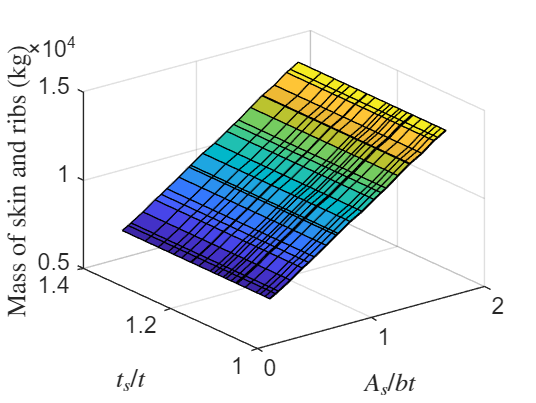

totalM(totalM == 0) = NaN;
[~,minidx] = min(totalM);
%minidx = length(wblist);
wb = wblist(minidx);
As_bt = As_bt_vals(minidx);
ts_t = ts_t_vals(minidx);


[X, Y] = meshgrid(As_bt_vals, ts_t_vals);
Z = repmat(totalM, length(ts_t_vals), 1);  % Replicate totalM along each row
figure(2);
clf;
surf(X, Y, Z);
xlabel('$A_s/bt$',"Interpreter","latex");
ylabel('$t_s/t$',"Interpreter","latex");
zlabel("Mass of skin and ribs (kg)","Interpreter","latex")
print(gcf, fullfile('images_new', 'Optimization.png'), '-dpng', '-r300')

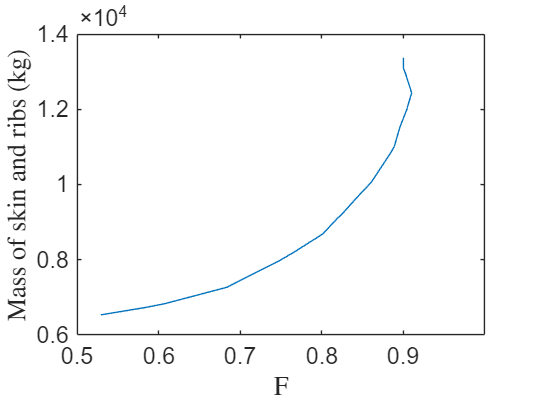


figure(3)
clf;
plot(Flist,totalM)
xlabel("F","Interpreter","latex")
ylabel("Mass of skin and ribs (kg)","Interpreter","latex")
print(gcf, fullfile('images_new', 'MvsF.png'), '-dpng', '-r300')

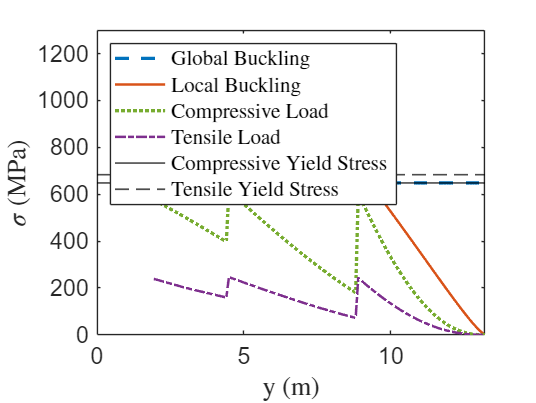



figure(5)
clf;
% Global Buckling: Solid Blue, Thick
sigmaGlobal =  wb.sr_s0.*wb.Ks_Upper.*E.*(wb.t_Upper./(wb.b1_c.*wing_opt.cn)).^2;
plot(wing_opt.stripy(wingidx), sigmaGlobal(wingidx)*1e-6, ...
    'LineStyle', '--', 'Color', [0, 0.4470, 0.7410], 'LineWidth', 2);
hold on;
% Local Buckling: Dashed Orange, Medium
sigmaLocal = wb.F.* sqrt(N.*E./wb.L);
sigmacr_Uskin = sigmaLocal;
plot(wing_opt.stripy(wingidx), sigmaLocal(wingidx).*1e-6, ...
    'LineStyle', '-', 'Color', [0.8500, 0.3250, 0.0980], 'LineWidth', 1.5);
% Compressive Load: Dotted Green, Thick
plot(wing_opt.stripy(wingidx), N(wingidx)./wb.t_Upper(wingidx)*1e-6, ...
    'LineStyle', ':', 'Color', [0.4660, 0.6740, 0.1880], 'LineWidth', 2);
sigma_Uskin = N./wb.t_Upper;
% Tensile Load: Dash-Dot Purple, Medium
plot(wing_opt.stripy(wingidx), -Nneg(wingidx)./wb.t_Upper(wingidx)*1e-6, ...
    'LineStyle', '-.', 'Color', [0.4940, 0.1840, 0.5560], 'LineWidth', 1.5);
% Compressive Yield: Solid Black
yline(sigmaY*1e-6, 'LineStyle', '-', 'Color', 'k', 'LineWidth', 1);
% Tensile Yield: Dashed Black
yline(sigmaYT*1e-6, 'LineStyle', '--', 'Color', 'k', 'LineWidth', 1);

legend("Global Buckling","Local Buckling","Compressive Load","Tensile Load",...
    "Compressive Yield Stress","Tensile Yield Stress", "Interpreter","latex","Location","northwest");
xlabel("y (m)", "Interpreter", "latex");
ylabel("$\sigma$ (MPa)", "Interpreter", "latex");
xlim([0 wing_opt.s]);
ylim([0 1300])
print(gcf, fullfile('images_new', 'UpperStressDiagram.png'), '-dpng', '-r300')



figure(7)
clf;
% Global Buckling: Solid Blue, Thick
sigmaGlobal =  wb.sr_s0_Lower.*wb.Ks_Lower.*E.*(wb.t_Lower./(wb.b1_c_Lower.*wing_opt.cn)).^2;
plot(wing_opt.stripy(wingidx), sigmaGlobal(wingidx)*1e-6, ...
    'LineStyle', '-', 'Color', [0, 0.4470, 0.7410], 'LineWidth', 2);
hold on;
sigmaLocal = wb.F_Lower.*sqrt(-Nneg.*E./wb.L)

sigmaLocal = 1.0e+08 *

         0    0.0708    0.1324    0.2008    0.2755    0.3547    0.4372    0.5225    0.6100    0.6993    0.7901    0.8822    0.9753    1.0694    1.1642    1.2597    1.3556    1.4520    1.5487    1.6457    1.7429    1.8403    1.9377    2.0352    2.1326    2.2300    2.3274    2.4246    2.5217    2.6186    2.7153    2.8118    2.9080    3.0041    3.0998    3.1952    3.2904    3.3852    3.4797    3.5739    3.6677    3.7612    3.8543    3.9470    4.0040    4.0951    4.0024    4.0887    4.1748    4.0345


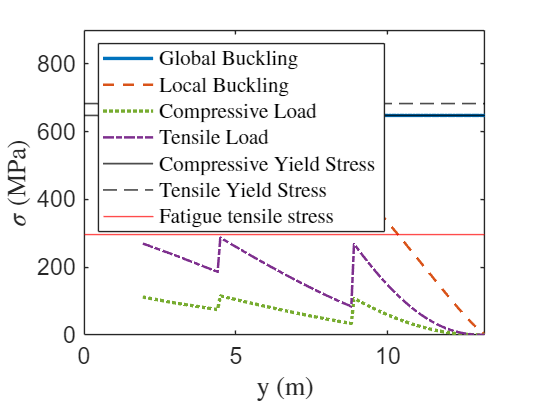

sigmacr_Lskin = sigmaLocal;
% Local Buckling: Dashed Orange, Medium
plot(wing_opt.stripy(wingidx), sigmaLocal(wingidx).*1e-6, ...
    'LineStyle', '--', 'Color', [0.8500, 0.3250, 0.0980], 'LineWidth', 1.5);
% Compressive Load: Dotted Green, Thick
plot(wing_opt.stripy(wingidx), -Nneg(wingidx)./wb.t_Lower(wingidx)*1e-6, ...
    'LineStyle', ':', 'Color', [0.4660, 0.6740, 0.1880], 'LineWidth', 2);
sigma_Lskin = -Nneg./wb.t_Lower;
% Tensile Load: Dash-Dot Purple, Medium
plot(wing_opt.stripy(wingidx), N(wingidx)./wb.t_Lower(wingidx)*1e-6, ...
    'LineStyle', '-.', 'Color', [0.4940, 0.1840, 0.5560], 'LineWidth', 1.5);
% Compressive Yield: Solid Black
yline(sigmaY_L*1e-6, 'LineStyle', '-', 'Color', 'k', 'LineWidth', 1);
% Tensile Yield: Dashed Black
yline(sigmaYT_L*1e-6, 'LineStyle', '--', 'Color', 'k', 'LineWidth', 1);
hold on
yline(sigma_max*1e-6,"r-")
legend("Global Buckling","Local Buckling","Compressive Load","Tensile Load",...
    "Compressive Yield Stress","Tensile Yield Stress","Fatigue tensile stress", "Interpreter","latex","Location","northwest");
xlabel("y (m)", "Interpreter", "latex");
ylabel("$\sigma$ (MPa)", "Interpreter", "latex");
xlim([0 wing_opt.s]);
ylim([0 900])
print(gcf, fullfile('images_new', 'LowerStressDiagram.png'), '-dpng', '-r300')

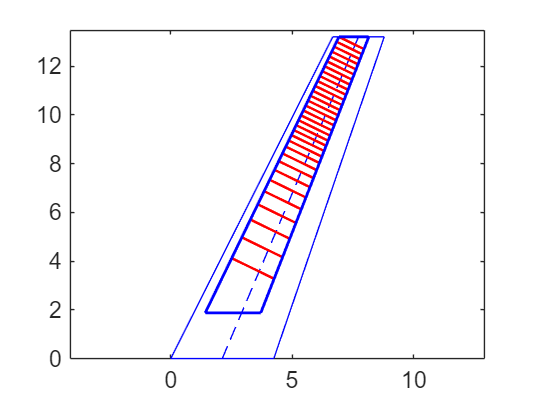



figure(6)
clf;
wing_opt.plotWing
hold on
wb.plotRibs(wing_opt)
hold on
wb.plotWingBox(wing_opt,D)
ylim([0 wing_opt.b/2*1.02])
axis equal
print(gcf, fullfile('images_new', 'RibsHT.png'), '-dpng', '-r300')

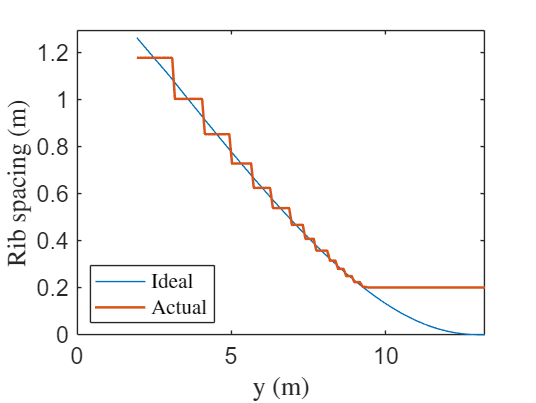


figure(4)
clf;
idealL = max(N.*E.*(sigmaY./wb.F).^(-2), 0);
plot(wing_opt.stripy(wingidx), max(idealL(wingidx),0),'Color', [0 0.4470 0.7410])
hold on
plot(wing_opt.stripy(wingidx), wb.L(wingidx),'LineWidth',1.5)
xlim([0, wing_opt.b/2])
ylim([0 max(wb.L*1.1)])
ylabel("Rib spacing (m)","Interpreter","latex")
xlabel("y (m)","Interpreter","latex")
legend("Ideal","Actual","Interpreter","latex","Location","southwest")
print(gcf, fullfile('images_new', 'RibSpacingHT.png'), '-dpng', '-r300');

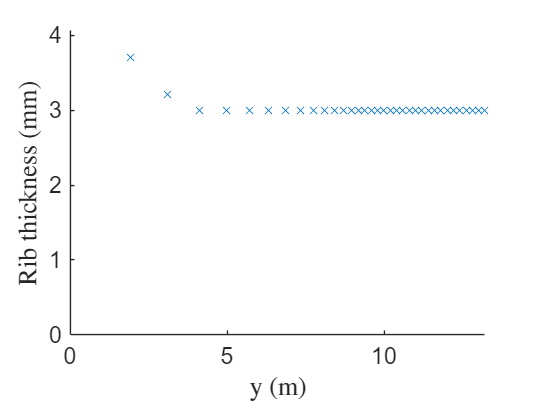


figure(5)
clf;
scatter(wb.yrib, wb.tr*1000,'x')
xlim([0, wing_opt.b/2])
ylim([0 max(wb.tr*1000*1.1)])
ylabel("Rib thickness (mm)","Interpreter","latex")
xlabel("y (m)","Interpreter","latex")
print(gcf, fullfile('images_new', 'RibThicknessHT.png'), '-dpng', '-r300');

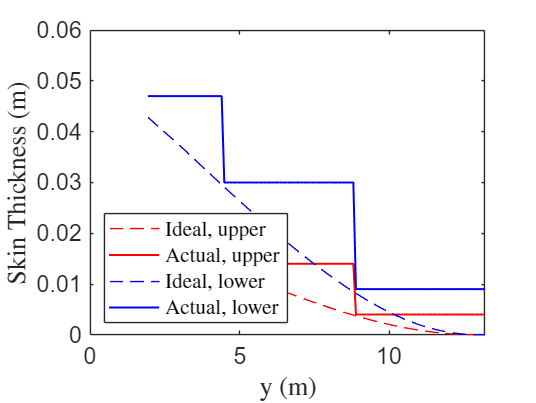


figure(6)
clf;
idealtUp = N./sigmaY;
idealtLow = N./sigma_max;

plot(ywing,idealtUp(wingidx),'r--')
hold on
plot(ywing, wb.t_Upper(wingidx),'r','LineWidth',1.2)
hold on
plot(ywing,idealtLow(wingidx),'b--')
hold on
plot(ywing,wb.t_Lower(wingidx),'b','LineWidth',1.2)
xlim([0, wing_opt.b/2])
ylim([0 0.06])
ylabel("Skin Thickness (m)","Interpreter","latex")
xlabel("y (m)","Interpreter","latex")
legend("Ideal, upper","Actual, upper","Ideal, lower","Actual, lower","Interpreter","latex","Location","southwest")
print(gcf, fullfile('images_new', 'SkinThickness.png'), '-dpng', '-r300');

## **3. Spar buckling analysis(get spar thickness)**

**Web is fixed at top/bottom, SS at sides (web stringers)**

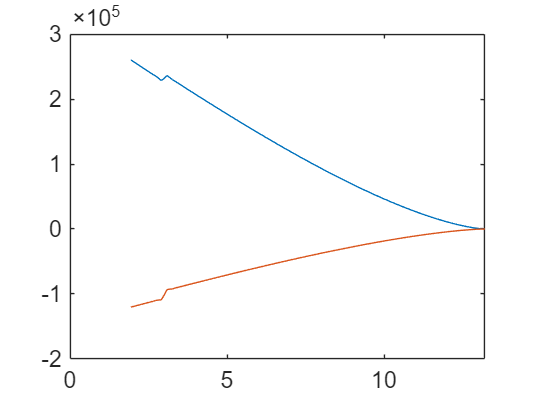

%[t_FS, t_RS] = Sparfun(wb, wing_opt,material,V,T,wbStress)

%for maximum buckling coefficient, let a = h
wb.a = wb.b2_c.*wing_opt.cn;
Ks = 8.1;
E = Al7068.E;

%Use same As/bt and ts/t
%z stringer
figure(1)
clf;
plot(wing_opt.stripy(wingidx), S(wingidx))
hold on
plot(wing_opt.stripy(wingidx), Sneg(wingidx))
xlim([0 wing_opt.b/2])

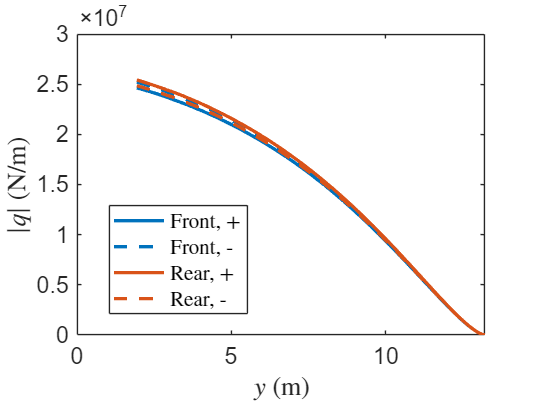


Awb = wb.c_c.*wb.b2_c.*wing_opt.cn.*wing_opt.cn;
hwb = wb.b2_c.*wing_opt.cn;

q = @(S,T,h,A) S./(2*h) + T./(2*A);

qFpos = q(-S,tau,hwb,Awb);
qFneg = q(-Sneg,tau,hwb,Awb);
qRpos = q(-S,-tau,hwb,Awb);
qRneg = q(-Sneg,-tau,hwb,Awb);

figure(2);
clf;

% Define line styles/colors for clarity
front_color = [0, 0.4470, 0.7410];  % Blue for front
rear_color = [0.8500, 0.3250, 0.0980];  % Red for rear
linewidth = 2;  % Thicker lines for visibility

% Plot front (+/-)
plot(wing_opt.stripy(wingidx), abs(qFpos(wingidx)), ...
    'Color', front_color, 'LineStyle', '-', 'LineWidth', linewidth);
hold on;
plot(wing_opt.stripy(wingidx), abs(qFneg(wingidx)), ...
    'Color', front_color, 'LineStyle', '--', 'LineWidth', linewidth);

% Plot rear (+/-)
plot(wing_opt.stripy(wingidx), abs(qRpos(wingidx)), ...
    'Color', rear_color, 'LineStyle', '-', 'LineWidth', linewidth);
plot(wing_opt.stripy(wingidx), abs(qRneg(wingidx)), ...
    'Color', rear_color, 'LineStyle', '--', 'LineWidth', linewidth);

% Formatting
legend("Front, +", "Front, -", "Rear, +", "Rear, -", ...
    'Interpreter', 'latex', 'Location', 'best');
ylabel("$\left| q \right|$ (N/m)", "Interpreter", "latex");
xlabel("$y$ (m)", "Interpreter", "latex");
xlim([0, wing_opt.b/2]);

[y_spar_s, N_spar_s] = createRibLocationsFromL(wb.b2_c.*wing_opt.cn, wing_opt, D);
y_wing = wing_opt.stripy;
yrib   = y_spar_s;

% Sort yrib if not already sorted
yrib = sort(yrib);

% Pre-allocate L
L = zeros(size(y_wing));

for i = 1:length(y_wing)
    y_i = y_wing(i);

    % 1) Check if y_i is within [-D/2, D/2]
    if (y_i >= -D/2) && (y_i <= D/2)
        % If in the fuselage region, set L to NaN
        L(i) = NaN;
    else
        % 2) Otherwise, find the adjacent ribs
        k = find(yrib <= y_i, 1, 'last');

        if isempty(k)
            % y_i < yrib(1)
            L(i) = yrib(2) - yrib(1);
        elseif k == length(yrib)
            % y_i >= yrib(end)
            L(i) = yrib(end) - yrib(end-1);
        else
            % y_i lies between yrib(k) and yrib(k+1)
            L(i) = yrib(k+1) - yrib(k);
        end
    end
end

a = L;
wb.a = L;

% Initialize an array to store the indices
sparidx = NaN(size(y_spar_s)); % Use NaN for excluded points

% Loop through each point in y_spar_s
for i = 1:length(y_spar_s)
    % Find the index of the closest point in wing_opt.stripy
    [~, idx] = min(abs(wing_opt.stripy - y_spar_s(i)));
    
    % Check if the corresponding wing_opt.stripy value is within the desired range
    if abs(wing_opt.stripy(idx)) >= D/2
        sparidx(i) = idx; % Store the index if the condition is satisfied
    end
    % Otherwise, sparidx(i) remains NaN (excluded)
end



figure(3)
clf;

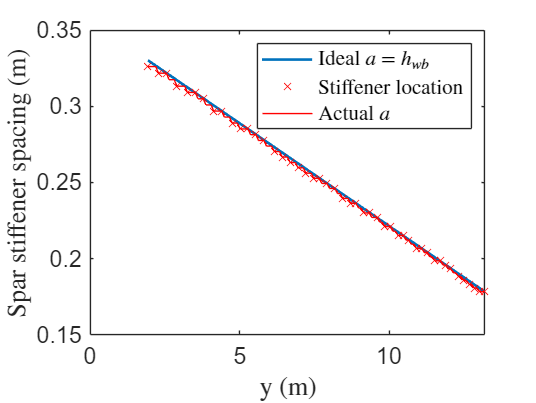

plot(wing_opt.stripy(wingidx), wb.b2_c.*wing_opt.cn(wingidx),'LineWidth',1.6)
hold on
scatter(wing_opt.stripy(sparidx), wb.a(sparidx),'x','r')
hold on
plot(wing_opt.stripy(wingidx), wb.a(wingidx),'r')
legend("Ideal $a$ = $h_{wb}$","Stiffener location","Actual $a$", "Interpreter", "latex")
xlabel("y (m)", "Interpreter", "latex")
ylabel("Spar stiffener spacing (m)", "Interpreter", "latex")
xlim([0 wing_opt.b/2])
print(gcf, fullfile('images_new', 'aspar.png'), '-dpng', '-r300');

wb.y_sparS = wing_opt.stripy(sparidx);

q_FS = abs(qFneg);
q_RS = abs(qRpos);

t_FS = (q_FS .* b2 ./ Ks ./ E).^(1/3);%thickness front spar
t_RS = (q_RS .* b2 ./ Ks ./ E).^(1/3);%thickness

tFd = [0.019 0.016 0.011]

tFd =     0.0190    0.0160    0.0110


tRd = [0.02 0.018 0.013]

tRd =     0.0200    0.0180    0.0130



wb.tF = thicknessDoubler(flip(t_FS),wing_opt.stripy,D)

wb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: [0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 … ] (1×301 double)
             tR: []
            c_c: 0.5800
           b1_c: [0.0519 0.0516 0.0512 0.0509 0.0506 0.0502 0.0499 0.0496 

wb.tR = thicknessDoubler(flip(t_RS),wing_opt.stripy,D)

wb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: [0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 … ] (1×301 double)
             tR: [0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.0180 0.

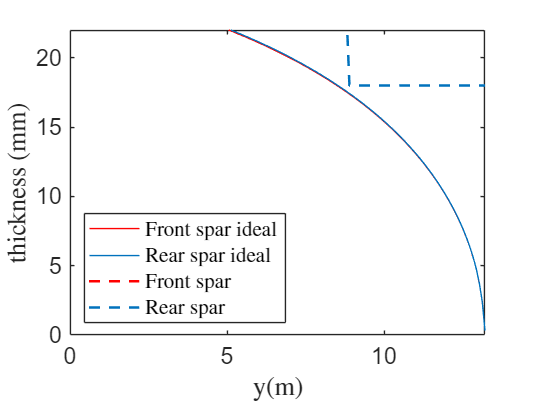



figure(4)
clf;
plot(wing_opt.stripy(wingidx),t_FS(wingidx)*1000,'r')
hold on
plot(wing_opt.stripy(wingidx),t_RS(wingidx)*1000,'Color', [0 0.4470 0.7410])
hold on
plot(wing_opt.stripy(wingidx),wb.tF(wingidx)*1000,'r--','LineWidth',1.5)
hold on
plot(wing_opt.stripy(wingidx),wb.tR(wingidx)*1000, 'Color', [0 0.4470 0.7410], 'LineStyle', '--', 'LineWidth', 1.5)
legend("Front spar ideal","Rear spar ideal", "Front spar","Rear spar","Location","SouthWest","Interpreter", "latex")
xlim([0, wing_opt.b/2]);
xlabel("y(m)", "Interpreter", "latex")
ylabel("thickness (mm)", "Interpreter", "latex")
ylim([0 0.022*1000])
print(gcf, fullfile('images_new', 'tspar.png'), '-dpng', '-r300');


t_sFS = ts_t * wb.tF;
t_sRS = ts_t * wb.tR;

%hs = (1.672 a t)/(1.6 ts)
h_sFS = (As_bt.*wb.a.*wb.tF)./(1.6.*t_sFS)

h_sFS =     0.0338    0.0338    0.0338    0.0343    0.0343    0.0347    0.0347    0.0352    0.0352    0.0357    0.0357    0.0361    0.0361    0.0366    0.0366    0.0371    0.0371    0.0376    0.0376    0.0376    0.0381    0.0381    0.0387    0.0387    0.0392    0.0392    0.0392    0.0397    0.0397    0.0402    0.0402    0.0408    0.0408    0.0408    0.0413    0.0413    0.0419    0.0419    0.0419    0.0425    0.0425    0.0430    0.0430    0.0430    0.0436    0.0436    0.0436    0.0442    0.0442    0.0448


h_sRS = (As_bt.*wb.a.*wb.tR)./(1.6.*t_sRS)

h_sRS =     0.0338    0.0338    0.0338    0.0343    0.0343    0.0347    0.0347    0.0352    0.0352    0.0357    0.0357    0.0361    0.0361    0.0366    0.0366    0.0371    0.0371    0.0376    0.0376    0.0376    0.0381    0.0381    0.0387    0.0387    0.0392    0.0392    0.0392    0.0397    0.0397    0.0402    0.0402    0.0408    0.0408    0.0408    0.0413    0.0413    0.0419    0.0419    0.0419    0.0425    0.0425    0.0430    0.0430    0.0430    0.0436    0.0436    0.0436    0.0442    0.0442    0.0448


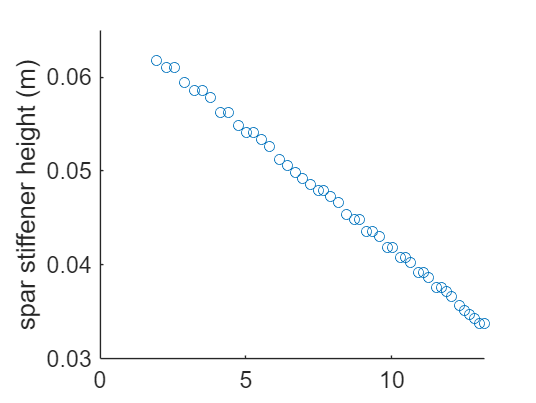

figure(5)
clf;
scatter(wing_opt.stripy(sparidx), h_sFS(sparidx))
ylabel("spar stiffener height (m)")
xlim([0 wing_opt.b/2])
print(gcf, fullfile('images_new', 'hss.png'), '-dpng', '-r300');


% %Verify interactive buckling in spar
% %check front spar
% tau_cr = 8.1*E.*(wb.tF./wb.a).^2;
% tau_cr_tresca = 125*1e6;
% tau_0 = qFneg./wb.tF;
% 
% Asbt_spar = t_sFS.*h_sFS*1.6./(wb.a.*t_sFS);
% ts_t_spar = 1.076;
% 
% R_c = interpsr_s0(Asbt_spar,ts_t_spar);
% R_s = tau_cr_tresca/tau_0;

IxFS = 1/12*wb.tF.*(wb.b2_c.*wing_opt.cn).^3;
sigma_cFS = M.*wb.b2_c.*wing_opt.cn/2./IxFS

sigma_cFS = 1.0e+10 *

         0    0.0001    0.0003    0.0009    0.0018    0.0031    0.0049    0.0071    0.0098    0.0129    0.0166    0.0208    0.0256    0.0308    0.0366    0.0430    0.0499    0.0573    0.0653    0.0738    0.0828    0.0924    0.1026    0.1132    0.1244    0.1361    0.1484    0.1611    0.1743    0.1881    0.2023    0.2170    0.2322    0.2478    0.2640    0.2805    0.2976    0.3150    0.3329    0.3513    0.3700    0.3892    0.4088    0.4287    0.4491    0.4698    0.4910    0.5124    0.5343    0.5565



IxRS = 1/12*wb.tR.*(wb.b2_c.*wing_opt.cn).^3;
sigma_cRS = M.*wb.b2_c.*wing_opt.cn/2./IxRS

sigma_cRS = 1.0e+10 *

         0    0.0001    0.0003    0.0009    0.0018    0.0031    0.0049    0.0071    0.0098    0.0129    0.0166    0.0208    0.0256    0.0308    0.0366    0.0430    0.0499    0.0573    0.0653    0.0738    0.0828    0.0924    0.1026    0.1132    0.1244    0.1361    0.1484    0.1611    0.1743    0.1881    0.2023    0.2170    0.2322    0.2478    0.2640    0.2805    0.2976    0.3150    0.3329    0.3513    0.3700    0.3892    0.4088    0.4287    0.4491    0.4698    0.4910    0.5124    0.5343    0.5565


## 4. Dcell

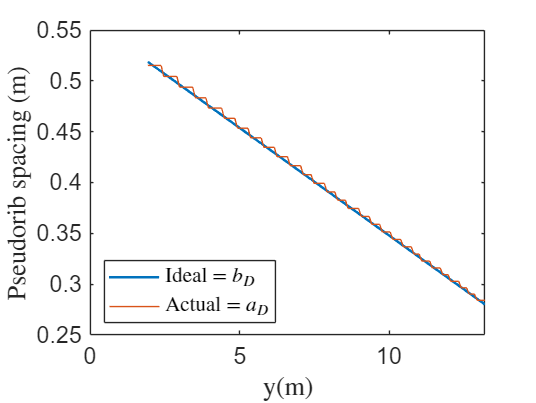

sigmaY = Al7068.sigma_y_tensile;
sigma_yield_tens = Al7068.sigma_y_tensile; % [Pa] From your material data
E = Al7068.E;                              % [Pa] Young’s modulus
b_D = pi * wb.R_c .* wing_opt.cn;          % [m] D-cell circumference (already computed)
[yprib, Nprib] = createRibLocationsFromL(b_D, wing_opt, D);

y_wing = wing_opt.stripy;
yrib   = yprib;

% Sort yrib if not already sorted
yrib = sort(yrib);

% Pre-allocate L
L = zeros(size(y_wing));

for i = 1:length(y_wing)
    y_i = y_wing(i);

    % 1) Check if y_i is within [-D/2, D/2]
    if (y_i >= -D/2) && (y_i <= D/2)
        % If in the fuselage region, set L to NaN
        L(i) = NaN;
    else
        % 2) Otherwise, find the adjacent ribs
        k = find(yrib <= y_i, 1, 'last');

        if isempty(k)
            % y_i < yrib(1)
            L(i) = yrib(2) - yrib(1);
        elseif k == length(yrib)
            % y_i >= yrib(end)
            L(i) = yrib(end) - yrib(end-1);
        else
            % y_i lies between yrib(k) and yrib(k+1)
            L(i) = yrib(k+1) - yrib(k);
        end
    end
end

wb.a_D = L;

figure(1)
clf;
plot(wing_opt.stripy(wingidx),b_D(wingidx),'LineWidth',1.5)
hold on
plot(wing_opt.stripy(wingidx),wb.a_D(wingidx))
legend("Ideal = $b_D$","Actual = $a_D$","Location","SouthWest","Interpreter", "latex")
xlim([0, wing_opt.b/2]);
xlabel("y(m)", "Interpreter", "latex")
ylabel("Pseudorib spacing (m)", "Interpreter", "latex")
print(gcf, fullfile('images_new', 'pseudorib.png'), '-dpng', '-r300');


wb.Nprib =58; 

a_D = wb.a_D;
b_D = pi*wb.R_c.*wing_opt.cn;
R = wb.R_c.*wing_opt.cn;
taumax = sigmaY/2;

%initial guess
t1 = 10e-3*ones(size(wing_opt.stripy));
t2 = 10e-3*ones(size(wing_opt.stripy));
converged = false

converged = logical
   0


iter = 0 

iter = 0

maxiter = 6

maxiter = 6

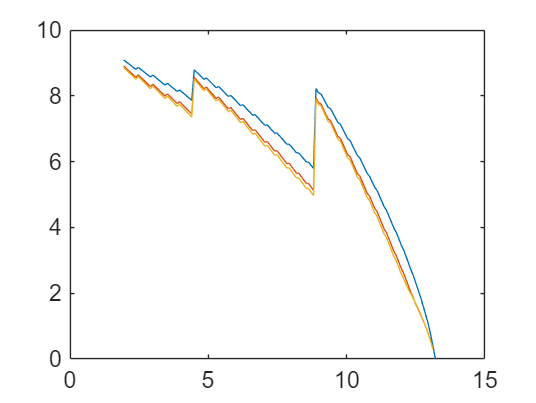

    0.0091

    0.0089



Converged


    0.0089



figure
while converged == false && iter < maxiter
    q_D = [];
    t1 = real(t2);
    for j =1:length(wingidx)
        i = wingidx(j);
        [~, q_D(i)] = shearFlow(wing_opt.cn(i), wb, tau(i), wb.t_Upper(i), wb.t_Lower(i), wb.tF(i), wb.tR(i), t1(i));
        %shear stress = q / t = buckling shear stress
    end
    b_RT = b_D./sqrt(R.*t1);
    b_RT = b_RT(wingidx);
    Ks = [];
    for j =1:length(wingidx)
        i = wingidx(j);
        Ks(i) = interpKspolyfit(R(i),t1(i),a_D(i),b_D(i));
    end
    %t2 = q_D./(Ks.*E.*t1.^2./b_D.^2);
    t2 = b_D.*sqrt((q_D./t1)./(Ks.*E));
    if abs(max(t2) - max(t1)) < 1e-4
        converged = true;
        disp("Converged")
    end
    plot(wing_opt.stripy(wingidx),t2(wingidx)*1000)
    hold on
    iter = iter + 1;
    disp(max(t2))
    %converged = true
end

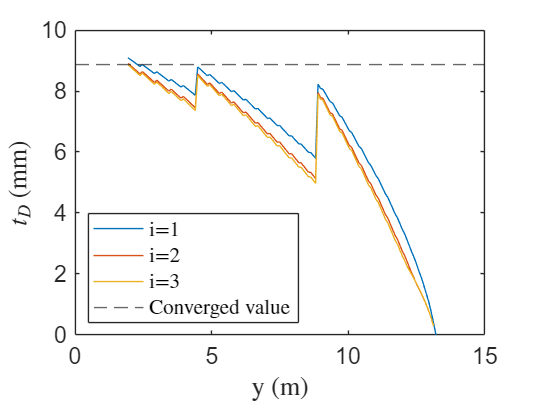

hold on
yline(max(t2)*1000,'--')
xlabel("y (m)","Interpreter","latex")
ylabel("$t_D$ (mm)","Interpreter","latex")
legend("i=1","i=2","i=3","Converged value","Interpreter","Latex","Location","SouthWest")

wb.tD = max(t2);
wb.tr_D = 3e-3;

%print(gcf, fullfile('images_new', 'tD.png'), '-dpng', '-r300');

Interactive Buckling

Verify for upper and lower skin, front and rear spar

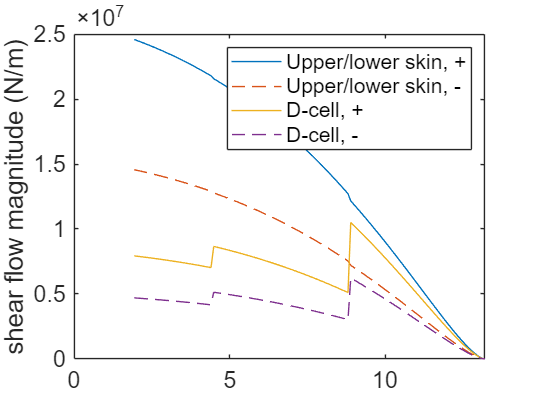

qF = -S./(2.*wb.b2_c.*wing_opt.cn);
qFneg = -Sneg./(2.*wb.b2_c.*wing_opt.cn);



q_wb = [];
q_D = [];
q_wbneg = [];
q_Dneg = [];
for j = 1:length(wingidx)
    i = wingidx(j);
    [q_wb(i), q_D(i)] = shearFlow(wing_opt.cn(i), wb, tau(i), wb.t_Upper(i), wb.t_Lower(i), wb.tF(i), wb.tR(i), wb.tD);
    [q_wbneg(i), q_Dneg(i)] = shearFlow(wing_opt.cn(i), wb, tauneg(i), wb.t_Upper(i), wb.t_Lower(i), wb.tF(i), wb.tR(i), wb.tD);
end



figure(1)
clf;
plot(wing_opt.stripy(wingidx),q_wb(wingidx))
hold on
plot(wing_opt.stripy(wingidx),abs(q_wbneg(wingidx)),'--')
hold on
plot(wing_opt.stripy(wingidx),abs(q_D(wingidx)))
hold on
plot(wing_opt.stripy(wingidx),abs(q_Dneg(wingidx)),'--')
legend("Upper/lower skin, +","Upper/lower skin, -","D-cell, +","D-cell, -")
ylabel("shear flow magnitude (N/m)")
xlim([0 wing_opt.b/2])



%in upper skin, q_wb
RcU = sigma_Uskin./sigmacr_Uskin

RcU =        NaN    0.0094    0.0212    0.0344    0.0488    0.0640    0.0798    0.0962    0.1129    0.1300    0.1473    0.1649    0.1826    0.2006    0.2187    0.2368    0.2551    0.2735    0.2919    0.3104    0.3289    0.3474    0.3660    0.3845    0.4031    0.4216    0.4401    0.4586    0.4771    0.4955    0.5139    0.5323    0.5506    0.5689    0.5871    0.6052    0.6233    0.6414    0.6593    0.6772    0.6951    0.7129    0.7306    0.7482    0.7725    0.7901    0.8447    0.8630    0.8812    0.9497


RsU = q_wb./wb.t_Upper./(sigmaYT./2)*0.1

RsU =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%in lower skin, q_wb
RcL = sigma_Lskin./sigmacr_Lskin

RcL =        NaN    0.0038    0.0071    0.0107    0.0147    0.0189    0.0233    0.0279    0.0326    0.0373    0.0422    0.0471    0.0521    0.0571    0.0622    0.0673    0.0724    0.0775    0.0827    0.0879    0.0931    0.0983    0.1035    0.1087    0.1139    0.1191    0.1243    0.1295    0.1347    0.1398    0.1450    0.1501    0.1553    0.1604    0.1655    0.1706    0.1757    0.1808    0.1858    0.1908    0.1959    0.2008    0.2058    0.2108    0.2176    0.2226    0.2379    0.2431    0.2482    0.2674


RsL = q_wb./wb.t_Lower./(sigmaYT_L./2)*0.1

RsL =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



xspace = linspace(0,1,100);
figure(2)
clf;
scatter(RcU(wingidx),RsU(wingidx),'x')
hold on
scatter(RcL(wingidx),RsL(wingidx),'.')
hold on
plot(xspace, sqrt(0.99-xspace),'k','LineWidth',1.5)

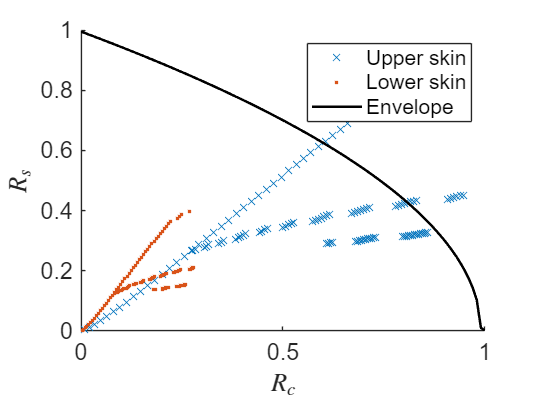

xlabel("$R_c$","Interpreter","latex")
ylabel("$R_s$","Interpreter","latex")
legend("Upper skin","Lower skin","Envelope")

print(gcf, fullfile('images_new', 'Interactive Buckling.png'), '-dpng', '-r300');


%find index that RcU + RsU^2 > 0.99
idx = find(RcU + RsU.^2 > 0.99);
wing_opt.stripy(idx)

ans =     4.4897    4.5777    4.6658    4.7538    4.8418    4.9299    5.0179    5.1059    5.1940    8.8914    8.9794    9.0674    9.1555    9.2435    9.3315    9.4196    9.5076    9.5956    9.6837    9.7717    9.8597    9.9478   10.0358   10.1238


[Mass_Lskin,M_Lskin,M_Lskin_stringer,thiswb.b1_c_Lower] = LskinMass(rho_Lskin, wing_opt, thiswb, wingidx)

Mass_Lskin = 9.0186e+03

M_Lskin = 3.1586e+03

M_Lskin_stringer = 5.8600e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0522 0.0519 0.0516 0.0512 0.0509 0.0506 0.0502 0.0499 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0469 0.0466 0.0464 0.0461 0.0458 0.0456 0.0453 0.0450 0.0448 0.0445 0.0443 0.0440 0.0438 0.0435 … ] (1×301 double)
     b1_c_Lower: [0.1176 0.1168 0.1160 0.1152 0.11

[Mass_Uskin,M_Uskin,M_Uskin_stringer,thiswb.b1_c] = UskinMass(rho_Uskin, wing_opt, thiswb, wingidx)

Mass_Uskin = 4.1628e+03

M_Uskin = 1.4690e+03

M_Uskin_stringer = 2.6938e+03

thiswb =   wingbox with properties:

            t_D: []
        t_Upper: [0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 0.0040 … ] (1×301 double)
        t_Lower: [0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 0.0090 … ] (1×301 double)
             tF: []
             tR: []
            c_c: 0.5800
           b1_c: [0.0522 0.0519 0.0516 0.0512 0.0509 0.0506 0.0502 0.0499 0.0496 0.0493 0.0490 0.0487 0.0484 0.0481 0.0478 0.0475 0.0472 0.0469 0.0466 0.0464 0.0461 0.0458 0.0456 0.0453 0.0450 0.0448 0.0445 0.0443 0.0440 0.0438 0.0435 … ] (1×301 double)
     b1_c_Lower: [0.1176 0.1168 0.1160 0.1152 0.11



M_Uskin

M_Uskin = 1.4690e+03

M_Uskin_stringer

M_Uskin_stringer = 2.6938e+03

Mass_Uskin

Mass_Uskin = 4.1628e+03


M_Lskin

M_Lskin = 3.1586e+03

M_Lskin_stringer

M_Lskin_stringer = 5.8600e+03

Mass_Lskin

Mass_Lskin = 9.0186e+03


Mrib = ribMass(thiswb, wing_opt, rho_r)

Mrib = 187.7832


%4. front spar
ywing = wing_opt.stripy(wingidx);
tFwing = wb.tF(wingidx);
hF = [];
for i = 1:length(ywing)
    hF(i) = wb.b2_c.*wing_opt.c_at_y(ywing(i));
end
V_FS = trapz(ywing, hF.*tFwing)*2;
As_FS = h_sFS(wingidx).*t_sFS(wingidx).*(1 + 0.3*2);
V_FS_skin = V_FS;
V_FS_stiffeners =  trapz(ywing,As_FS)*2;
V_FS = V_FS  +V_FS_stiffeners;
MFS_stiffeners = V_FS_stiffeners*Al7068.rho;
MFS = V_FS*Al7068.rho

MFS = 481.6198

MFS_total = V_FS*Al7068.rho

MFS_total = 481.6198



%5. rear spar
tRwing = wb.tR(wingidx);
V_RS = trapz(ywing, hF.*tRwing);
As_RS = h_sRS(wingidx).*t_sRS(wingidx).*(1 + 0.3*2);
V_RS_skin = V_RS;
V_RS_stiffeners =  trapz(ywing,As_RS)*2;
V_RS = V_RS  +V_RS_stiffeners;
MRS_stiffeners = V_RS_stiffeners*Al7068.rho

MRS_stiffeners = 122.9516

MRS = V_RS*Al7068.rho

MRS = 302.2857

MRS_total = V_RS*Al7068.rho

MRS_total = 302.2857


%6. D cell
V_D = trapz(ywing, wb.tD.*pi.*wb.R_c.*wing_opt.cn(wingidx))*2;
V_Dr = sum(wb.tr_D.*1/2.*pi*(wb.R_c.*wing_opt.cn(wingidx)).^2)*2;
V_D_total = V_D + V_Dr;
MD = V_D*Al7068.rho

MD = 227.4047

MD_pr = V_Dr*Al7068.rho

MD_pr = 57.6588

MD_total = V_D_total*Al7068.rho

MD_total = 285.0635


total = Mass_Uskin + Mass_Lskin + Mrib + MFS_total + MRS_total + MD_total

total = 1.4438e+04

M_Uskin.*Al7068.price

ans = 5.3030e+03

M_Uskin_stringer.*Al7068.price

ans = 9.7248e+03



M_Lskin.*Al7068.price

ans = 1.1403e+04

M_Lskin_stringer.*Al7068.price

ans = 2.1155e+04


Mrib.*Al7068.price

ans = 677.8975


MFS_stiffeners.*Al7068.price

ans = 443.8553

MFS.*Al7068.price

ans = 1.7386e+03


MRS_stiffeners.*Al7068.price

ans = 443.8553

MRS.*Al7068.price

ans = 1.0913e+03


MD.*Al7068.price

ans = 820.9311

MD_pr.*Al7068.price

ans = 208.1483